# **MATLAB Examples  of Numerical Programming**

**by Y.-K. Kim**

## How to use MATLAB built in functions

# Non-linear solver

First, define a non-linear function in the form of f(v)=0. Then, use a non-linear equation solver fzero ().

          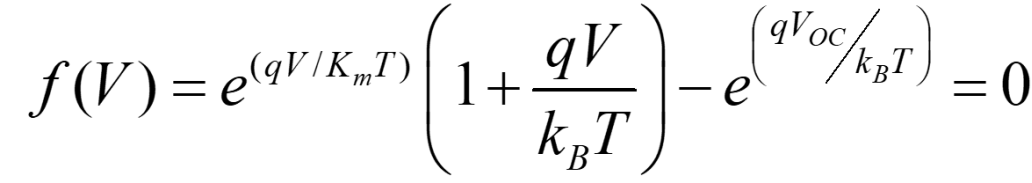                                                    

v0=0.5;
v=fzero(@fnSolarCell,v0)

% function y=fnSolarCell(x)
%     q=1.6022E-19; k=1.3806E-23; Voc=0.5; T=297;
%     qkT=q/(k*T);
%     y=exp(qkT*x)*(1+qkT*x)-exp(qkT*Voc);
% end

# Integration

## Integrating discrete dataset: trapz()

Trapezoidal Method

% Discrete dataset
x=[0 5 10 15 20 25 30 35 40 45 50 55 60]
y=[0 3 8 20 33 42 40 48 60 12 8 4 3]
plot(x,y)

% Matlab function
I_matlab = trapz(x,y);    

## Integrating a function:  integral(fun, a,b)

The area of the shaded region shown in the figure can be calculated by:

a=-3; b=3; N=8;
h=(b-a)/N;
x=a:h:b;
fun=@(x) (1-x.^2).^0.5;
% Matlab function
I_matlab = integral(fun,a,b);    

# Differentiation

## Differentiating discrete dataset

% Differentiation from discrete data
X = [1 1 2 3 5 8 13 21];
Y = diff(X)
% Differentiation from discrete data
h = 0.001;       % step size
X = -pi:h:pi;    % domain
f = sin(X);      % range
Y = diff(f)/h;   % first derivative
Z = diff(Y)/h;   % second derivative
plot(X(:,1:length(Y)),Y,'r',X,f,'b', X(:,1:length(Z)),Z,'k')

## **Differentiate a Function**

% Ordinary Differentiation of a function
syms x
g = exp(x)*cos(x);
diff(g)
% 2nd order Differentiation of a function
diff(g,2)
% Partial Differentiation of a function
syms s t
f = sin(s*t);
diff(f,t)

# Linear Equations

Solve for Ax=b

                              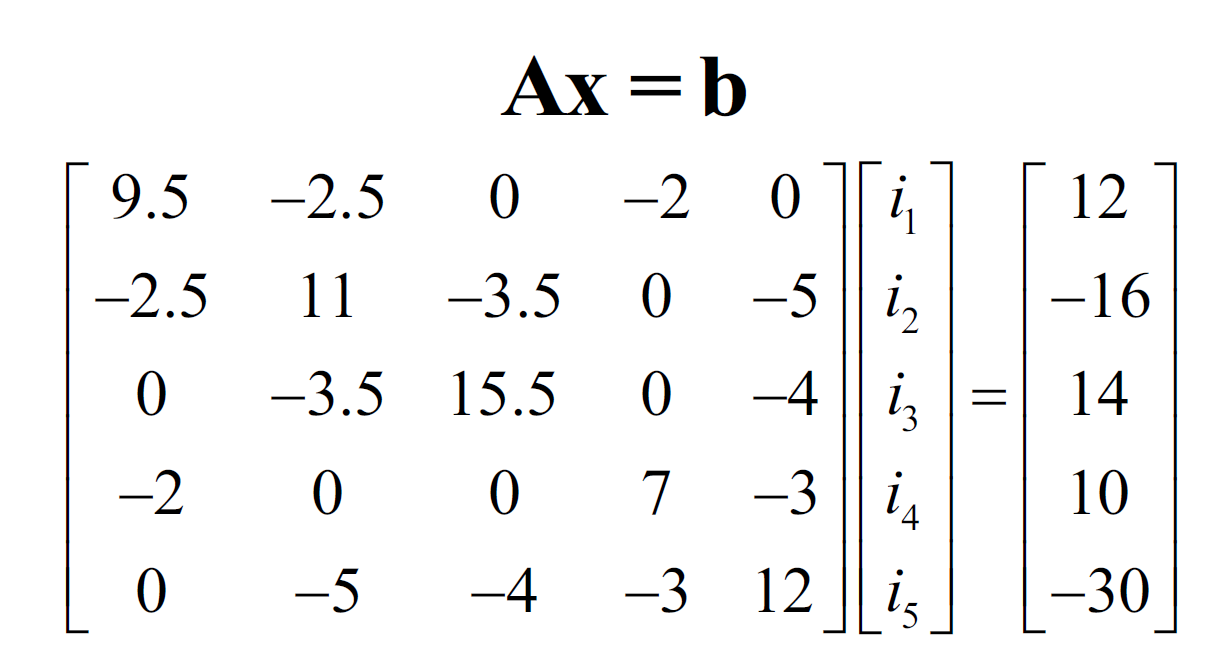

% A, b
A=[9.5, -2.5, 0, -2, 0;     -2.5, 11, -3.5, 0, -5;     0,-3.5, 15.5, 0, -4;     -2,  0,  0, 7, -3;     0, -5,  -4, -3, 12];
b=[12; -16; 14; 10; -30];

% solve for Ax=b
x=A\b   
x=inv(A)*b
% condition number
c=cond(A)
% norm 
n=norm(A)
% eigenvalue/vector
[eigVec,eigVa]=eig(A)
% QR factorization
[Q,R]=qr(A)

% LU factorization
[L,U]=lu(A)

# Polynomial Fitting

t = 1:1:15;
V=[2.272	2.092	1.887	1.629	1.482	1.308	1.030	0.875	0.693	0.470	0.336	0.095	-0.163	-0.371	-0.511];

% Matlab function for polynomial fit
Zopt=polyfit(t,V,1);
Yopt=polyval(Zopt,t);  % Matlab function

figure
plot(t,V, '*r')
hold on
plot(t,Yopt, '-b')
xlabel('time','fontsize',15)
ylabel('V','fontsize',15)

# Exponential Fitting

RC circuit with unknown capacitor C and resistor of 5M$\Omega$

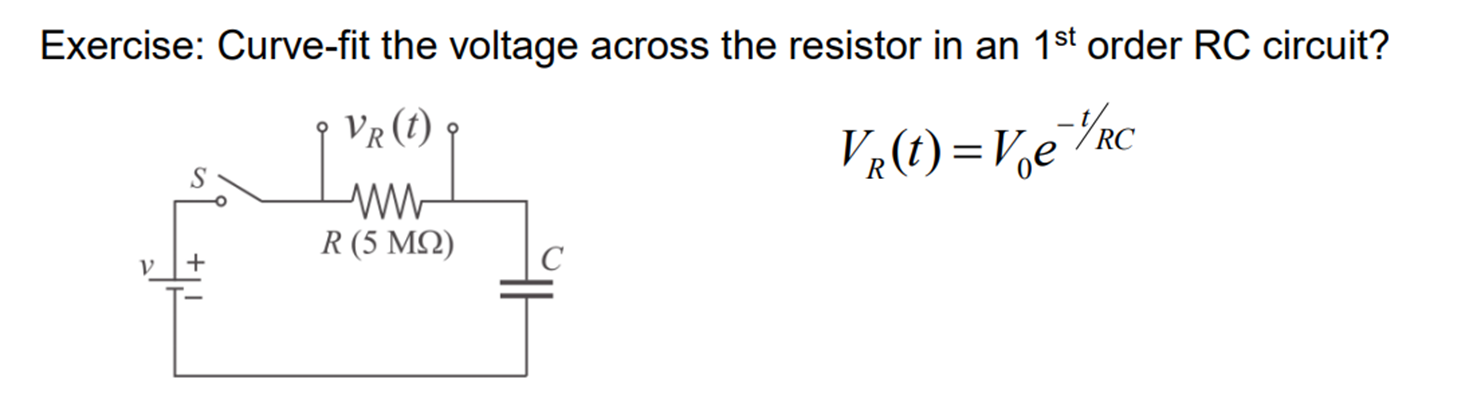

a) Find the capacitance  C from curve fitting

b) Esimate the voltage when time=32sec

Xdata = 1:1:15;
Ydata = [9.7 8.1 6.6 5.1 4.4 3.7 2.8 2.4 2.0 1.6 1.4 1.1 0.85 0.69 0.6];


% Matlab function
Zopt=polyfit(Xdata,log(Ydata),1)
R=5e6;
a0=Zopt(2);
a1=Zopt(1);
V0=exp(a0);
tau=-1/a1;
C=tau/R;

% Exponential model
Yopt=V0*exp(-1/(R*C).*Xdata);

figure
plot(Xdata,Ydata, '*r')
hold on
plot(Xdata,Yopt)
hold on
xlabel('time (s)','fontsize',15)
ylabel('V_R(volt)','fontsize',15)

# 1st order ODE-IVP

## Problem

Solve for the response of an RC circuit with a DC  input 

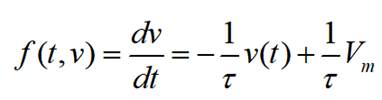

tau=  4.9919;   T=1/tau;  Vm=11.91;

Parameter Definitions

clear
% Initial Condition
a=0; b=15; h=1; 
y0 = 11.91;
t=a:h:b;

%% MATLAB's function ODE45
[tmat,vmat] = ode45(@myRC, [a b], y0);  % Fourth/Fifth RK
figure()
plot(tmat,vmat,'.b')
xlabel('time (s)','fontsize',15)
ylabel('V_R(volt)','fontsize',15)

% function dvdx = myRC(v)
%     tau=4.9919; T=1/tau;  Vm=11.91;
%     dvdx =-T*v + 1*T*Vm;
% end


# 2nd order ODE - IVP

Solve an m-c-k system with a sinusoidal input. 

Use  m=10kg ; k=800 N/m; c=200 N/(m/s), f=10Hz , h=0.01, Fdc=100N.

Parameter Definition

% Initial Condition
y0 = 0; v0 = 0;
Yinit = [y0 v0];
a=0; b=1; h=0.01;
tspan = [a:h:b];

% MATLAB's function ODE45
[Time Y] = ode45(@mckFunc,tspan,Yinit);

figure
subplot(2,1,1)
    plot(Time,Y(:,1),'--b')
    xlabel('Time (s)')
    ylabel('Position (m)')
    title('ode45')
subplot(2,1,2)
    plot(Time,Y(:,2),'k')
    xlabel('Time (s)')
    ylabel('Velocity (m/s)')

% function [dXdt] = mckFunc(t,x)
%     dXdt=zeros(2,1); % column vector
%     m=10; k=800; c=200; f=10;
%     FinDC=100;
%     Fin=FinDC*cos(2*pi*f*t);
%     dXdt(1)=x(2);
%     dXdt(2)=1/m*(Fin-c*x(2)-k*x(1));
% end


# Eigenvalue 

What are the eigenvalues for the given m-c-k system response? 

Use  m=10kg ; k=800 N/m; c=200 N/(m/s) 

k=800; c=200; m=10;
A = [0 1; -k/m, -c/m];
disp('Eigvalue and vector of A (MATLAB):');
[eigVec,eigVa]=eig(A)


# Functions

Functions used in this tutorial

function y=fnSolarCell(x)
    q=1.6022E-19; k=1.3806E-23; Voc=0.5; T=297;
    qkT=q/(k*T);
    y=exp(qkT*x)*(1+qkT*x)-exp(qkT*Voc);
end

function dvdx = myRC(t,v)
   tau=4.9919; T=1/tau;  Vm=0;
   dvdx =-T*v + 1*T*Vm;
end

function [dXdt] = mckFunc(t,x)
    dXdt=zeros(2,1); % column vector
    m=10; k=800; c=200; f=10;
    FinDC=100;

    Fin=FinDC*cos(2*pi*f*t);
    dXdt(1)=x(2);
    dXdt(2)=1/m*(Fin-c*x(2)-k*x(1));
end
